## ベイズ最適化を用いた制御器のチューニング  最適レギュレータのゲインを求めてみる

制御系設計論 9章 章末問題【4】 (1) の例題のLQRの結果に対し、

ベイズ最適化で同じような結果が簡単に得られるものなのか？？ を検証する。

#### 問題


$$\dot{x}(t) = \left(
\begin{array}{rr}
0 & 1 \\
1 & 1 \\
\end{array}
\right) x(t) + \left(
\begin{array}{rr}
0  \\
1  \\
\end{array}
\right) u(t)
$$


を考えたとき、二次形式評価関数


$$J = \int^\infty_0 \left\{ x(t)^{T} \left(
\begin{array}{rr}
3 & 0 \\
0 & 2 \\
\end{array}
\right) x(t) + u(t)^2
\right\} dt$$


を最小化するフィードバックゲインを求めよ

#### 答え

Riccati方程式の解

$P=\left(
\begin{array}{rr}
5 & 3 \\
3 & 4 \\
\end{array}
\right) $で、このとき最適フィードバックゲイン$K=-[3 \ 4]$

clear;
clf;


制御対象の設定

A = [0 1;1 1];
B = [0;1];
C = eye(2);

x_ini = [1;0];
sys = ss(A,B,C,0);

Q = [3 0; 0 2];
R = 1;

% [Klqr,P,~] = lqr(A,B,Q,R); 
Klqr = [3 4]; % 解析的に求まる最適ゲイン
P = [5 3; 3 4]; % Riccati方程式の解


Jmin = x_ini'*P*x_ini;

ベイズ最適化の準備

% ※ 初期ゲインの設定次第で、最適ゲインに近いものがすぐ求まったり、
% ※ 時間がかかったりとがけっこう変わる
Kini = [10 10]; 

K1 = optimizableVariable('K1',[1,10],'Type','real'); %real:実数、integer:整数
K2 = optimizableVariable('K2',[1,10],'Type','real'); %real:実数、integer:整数

f = @(x) J([x.K1 x.K2],sys,x_ini,Q,R);

ベイズ最適化実行

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |           K1 |           K2 |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |      8.5309 |   0.0046382 |      8.5309 |      8.5309 |           10 |           10 |
|    2 | Best   |      5.0642 |   0.0044481 |      5.0642 |      5.2497 |       2.8836 |       4.2346 |
|    3 | Accept |      23.825 |   0.0024755 |      5.0642 |      5.8485 |       8.1999 |       2.9819 |
|    4 | Accept |      5.7279 |   0.0048336 |      5.0642 |       5.068 |       2.7474 |       5.2631 |
|    5 | Accept |      140.44 |   0.0045867 |      5.0642 |      5.0593 |       3.8858 |       1.0156 |
|    6 | Accept |      5.4035 |   0.0022677 |      5.0642 |     

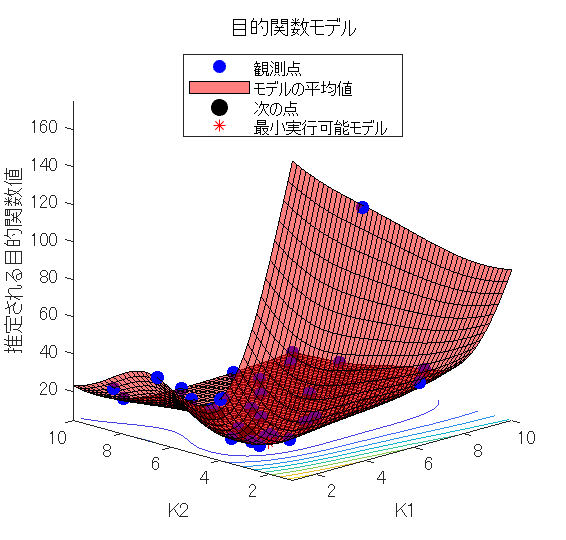

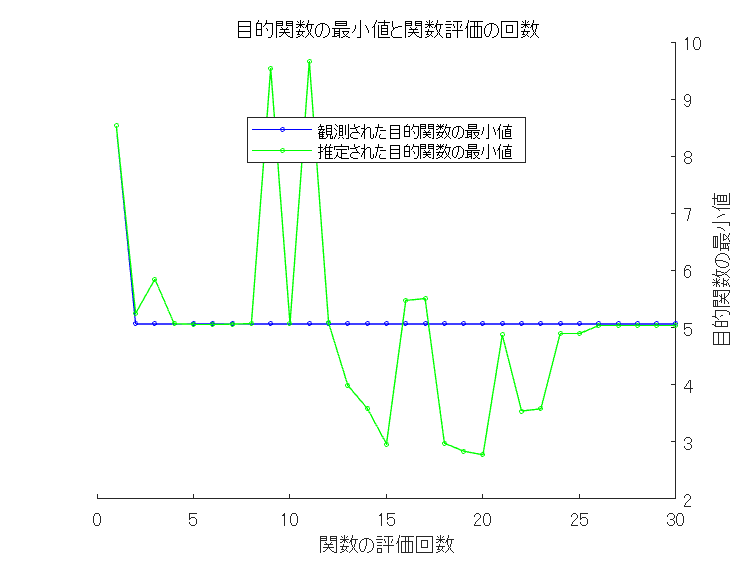

% デフォルトの獲得関数は実行時間を加味するので、毎回結果が異なる。
% 本来あまり使われない？が、今回は期待改善量(「プラス」なし)を選択
% https://jp.mathworks.com/help/stats/bayesian-optimization-algorithm.html
results = bayesopt(f,[K1,K2], ...
    'AcquisitionFunctionName','expected-improvement',... 
    'InitialX',array2table(Kini), ...
    'MaxObjectiveEvaluations',30,'MaxTime',60);

結果の確認

results.XAtMinObjective 

ans = 1×2 table
      K1        K2  
    ______    ______

    2.8836    4.2346


results.MinObjective    

ans = 5.0642


Kafter = table2array(results.XAtMinObjective);

% view(0,90) %3次元プロットされた評価関数を上から見る

# scratch領域

J(Klqr,sys,x_ini,Q,R) % 関数最小値Jminと同じはず

ans = 5.0138

J(Kini,sys,x_ini,Q,R) % 

ans = 8.5309

J(Kafter,sys,x_ini,Q,R) % 

ans = 5.0642

得られた制御器の性能確認

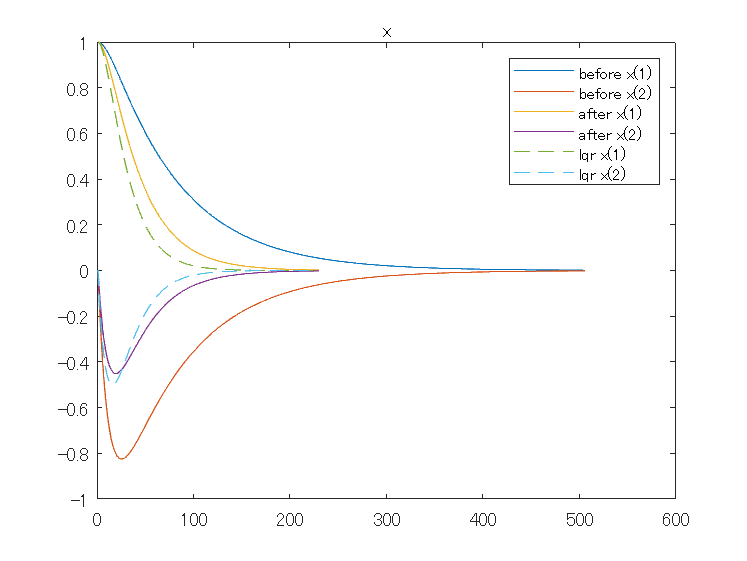

syslbefore = ss(A-B*Kini,B,C,0);
xbefore = initial(syslbefore,x_ini);
plot(xbefore);
hold on

syslafter = ss(A-B*Kafter,B,C,0);
xafter = initial(syslafter,x_ini);
plot(xafter);

sysllqr = ss(A-B*Klqr,B,C,0);
xlqr = initial(sysllqr,x_ini);
plot(xlqr,'--');
legend_x = legend({'before x(1)','before x(2)','after x(1)','after x(2)','lqr x(1)','lqr x(2)'});
legend_x.ItemHitFcn = @hitcallback_ex1; %凡例クリックしたら表示/非表示
title('x')
hold off

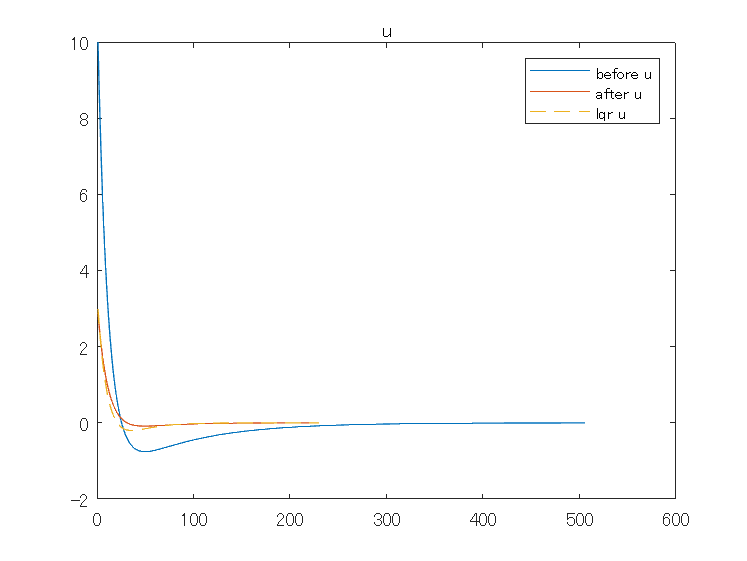


figure;
plot(Kini*xbefore');
hold on
plot(Kafter*xafter');
plot(Klqr*xlqr','--');
legend({'before u','after u', 'lqr u'});
title('u')
hold off

### 目的関数の設定

Euler法でシミュレーションループを回す簡易版

function val = J(K,sys,x_ini,Q,R)
    
    A = sys.A;
    B = sys.B;
    C = sys.C;
    
    % シミュレーションのパラメータ
    dt = 0.01; % 時間ステップ
    T = 10; % シミュレーションの終了時間
    
    % 初期化
    x = x_ini;
    J = 0;
    
    % % シミュレーションループ
    for t = 0:dt:T
        u = -K*x; % 制御入力
        x_dot = A*x + B*u; % 状態方程式
        x = x + x_dot * dt; % 状態の更新
        J = J + (x'*Q*x + u'*R*u) * dt; % コスト関数の更新
    end
    val = J;
end

グラフ描画用 凡例クリック時の表示/非表示

function hitcallback_ex1(src,evnt)

    if strcmp(evnt.Peer.Visible,'on')
        evnt.Peer.Visible = 'off';
    else 
        evnt.Peer.Visible = 'on';
    end

end